# Using the MCMC hammer for sampling the posterior distribution

## Add the folder with the functions to the path

cd ('/Users/razo/Documents/PhD/teaching/MBL_Physiology_2016/code/bayesian_inference')
addpath('mcmc_hammer/')

## Read data

df = readtable('flow_master.csv');
df(1:5,:)

ans =        date        username     operator    binding_energy       rbs       repressors    IPTG_uM    mean_YFP_A    mean_YFP_bgcorr_A    fold_change_A
    __________    __________    ________    ______________    _________    __________    _______    __________    _________________    _____________

    2.0161e+07    'mrazomej'    'O2'        -13.9             'auto'         0           0          3512.6             0                       0    
    2.0161e+07    'mrazomej'    'O2'        -13.9             'delta'        0           0           19164         15652                       1    
    2.0161e+07    'mrazomej'    'O2'        -13.9        

## Extract data for fitting to a single strain

% Extracting data of a single strain
O2_1027_rows = strcmp(df.operator, 'O2') & strcmp(df.rbs, 'RBS1027');
df_fit = df(O2_1027_rows, :);

% Extract specific variables used for fitting
indep_var = table2array(df_fit(:, {'IPTG_uM', 'repressors', 'binding_energy'}));
dep_var = df_fit.fold_change_A;
epsilon = 4.5;

## Define parameters for MCMC

% Define the parameters for emcee
n_dim = 3; % number of parameters to fit

n_walkers = 50;
n_burn = 100;
n_steps = 500;

## Initialize walkers

p0 = zeros([n_dim, n_walkers]);
p0(1:2, :) = unifrnd(-6, 6, [n_dim - 1, n_walkers]);
p0(3, :) = unifrnd(0.001, 1, [1, n_walkers]);

lp = @(param)mcmc_log_post(param, indep_var, dep_var, epsilon);
% lprior = @(param)mcmc_log_prior(param, indep_var, dep_var, epsilon);
% llike = @(param)mcmc_log_like(param, indep_var, dep_var, epsilon);
[m, logP] = gwmcmc(p0, lp,  n_walkers * (n_burn + n_steps), 'burnin', n_burn / (n_burn + n_steps),...
           'ProgressBar', false, 'Parallel', true);

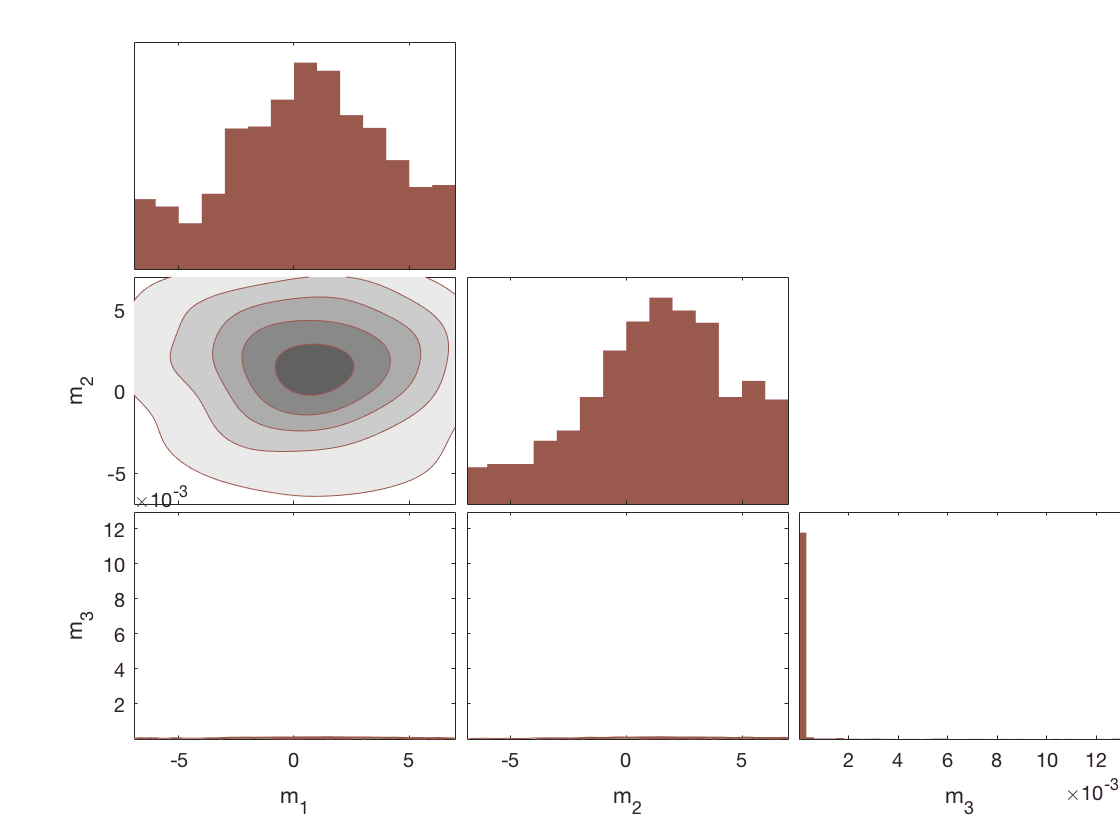

ecornerplot(m,'ks',false,'color',[.6 .35 .3])